# Jacobi approximation of a function

syms x real
fun = sin (2*pi*x)* exp (-x);

a = 6; b = 6 ;
w = (1-x)^a *(1+ x)^b; % weight function

N = 5;
J = jacobiP (0:N, a, b, x).' % J is sym with N+1 Jacobi polyn

$$J = \left(\begin{array}{c} 1\\ 7\,x\\ 30\,x^{2}-2\\ 102\,x^{3}-18\,x\\ \frac{4845\,x^{4}}{16}-\frac{765\,x^{2}}{8}+\frac{45}{16}\\ \frac{13167\,x^{5}}{16}-\frac{3135\,x^{3}}{8}+\frac{495\,x}{16} \end{array}\right)$$

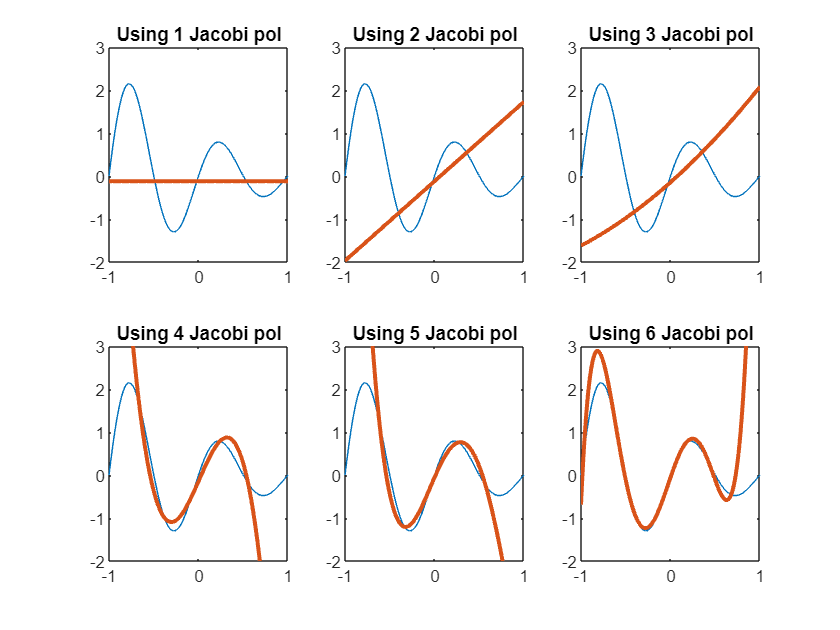


k = a+b+1;
phi = zeros (1,N +1); % preallocation of (N +1) double coeff

for n = 0:N
    Cn_2 = 2^k /(2*n+k)* gamma(n+a+1)* gamma(n+b+1)/(factorial(n)* gamma(n+k)); % squared norm
    phi(n+1) = vpaintegral (fun * J(n+1)*w,x , -1 ,1)/ Cn_2 ; % numerical integration
end

t = -1:0.01:1;
JacobiMatrix = subs(J, x, t); % evaluate J on a numerical array t

fun_approx = phi * JacobiMatrix; % phi is 1x(N+1) , JacobiMatrix is (N +1) x201

figure
for i = 1:N+1
    subplot(2,3,i)
    fplot(fun, [-1 1])
    ylim([-2 3])
    
    fun_approx = phi(1:i)*JacobiMatrix(1:i,:);
    hold on
    h = plot(t, fun_approx, LineWidth=2);
    title("Using "+ i + " Jacobi pol")
    
end